# **实验****二** **  线性系统二次型最优控制律**

专业班级：           学号：           姓名：        成绩：

## **一、实验目的**

- 掌握二次线性最优控制律设计方法；

- 了解MATLAB中的相应函数。

## **二、实验要求**

控制系统如下图所示

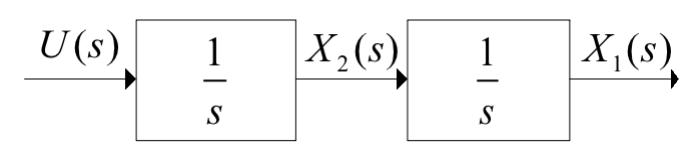

状态初值为 


$$x(0)=\pmatrix{1 & 2}^T$$


性能指标为

	
$$J = \int ^ \infty _0  [
x^T
\pmatrix{1 & 0 \cr 0 & 0}
x
+
u^2
]\mathrm{d} t$$


求：

- 系统的最优控制率及最优性能指标；

- 绘制最优控制率下的系统状态响应曲线。

##  三、实验内容及结果分析

### 3.1 系统的最优控制率及最优性能指标

从结构框图可以得出系统的状态方程如下：


$$\left\{\begin{array}{@{}ll@{}}

\dot{x_1}=x_2\\
\dot{x_2}=u\\
y=x_1

\end{array}


\Rightarrow

\left\{\begin{array}{@{}ll@{}}

\dot{x}=\pmatrix{
0 & 1 \cr 0 & 0
}x+\pmatrix{0 \cr 1}u
\\
y=\pmatrix{1& 0}x

\end{array}
$$


A=[0 1; 0 0];
B=[0 ; 1];
C=[1 0];
D=zeros(1,1);
G=ss(A,B,C,D);
x0=[1 2]';
Sc=ctrb(A,B);
So=obsv(A,C);
if rank(Sc) == length(A)
    disp('controllable')
end

controllable


if rank(So) == length(A)
    disp('Observable')
end

Observable


性能指标在MATLAB中使用的形式为


$$J(u)=\int^\infty _0 
(x^TQx+u^TRu+2x^TNu)
\mathrm{d} t$$


于是有可以通过[lqr](https://www.mathworks.com/help/releases/R2021a/control/ref/lqr.html?s_tid=doc_ta)命令求解最优控制率为：

Q=1*[1 0;0 0];
R=1;
N=zeros(size(x0',2),1);%N也可以直接使用零
%computes the unique solution X of the continuous-time algebraic Riccati equation
[P,l,g]=care(A,B,Q,R);%可以使用该命令计算矩阵P，与下一个命令的S相同
[K,S,~] = lqr(G,Q,R,N);
display(K);

K =     1.0000    1.4142


最优性能指标为：

J_star=1/2*x0'*S*x0

J_star = 5.5355

### 3.2 绘制最优控制率下的系统状态响应曲线

Ac=A-B*K;
Bc=zeros(size(B));
G2=ss(Ac,Bc,C,D);

     状态响应曲线及与原系统状态响应的对比图如下，从图中可以看出，原系统在零输入条件下无法稳定，而使用线性二次型优化控制后，系统很快就能到达平衡位置而保持稳定

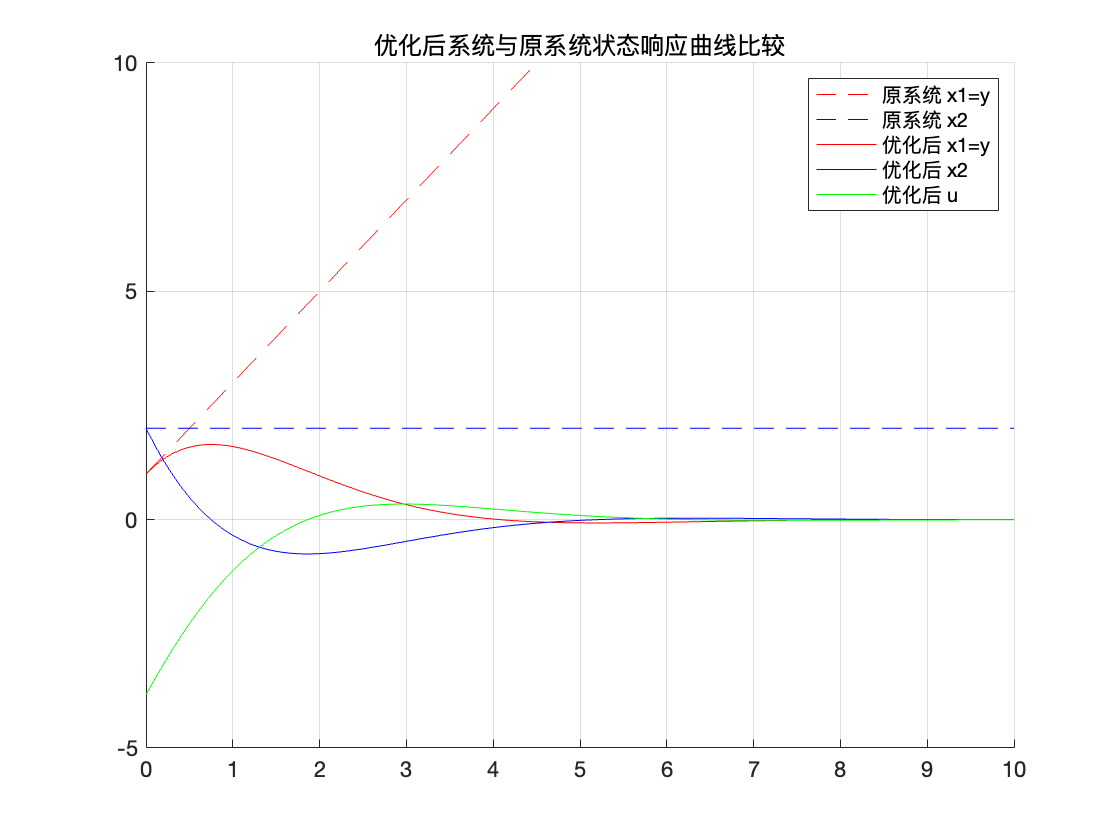

Tfinal=10;
[~,t,x]=initial(G,x0,Tfinal);
[~,t2,x2]=initial(G2,x0,Tfinal);
figure()
hold on;
plot(t,x(:,1),'r--','displayName','原系统 x1=y');
plot(t,x(:,2),'b--','DisplayName','原系统 x2');
plot(t2,x2(:,1),'r','DisplayName','优化后 x1=y');
plot(t2,x2(:,2),'b','DisplayName','优化后 x2');
u=-K*x2';
plot(t2,u,'g','DisplayName','优化后 u');
title('优化后系统与原系统状态响应曲线比较');
grid;
legend;
ylim([-5,10]);
hold off

##  3.3 参考链接

- Linear Quadratic Regulator (LQR) State Feedback Design.[Copyright F (uta.edu)](https://lewisgroup.uta.edu/Lectures/lqr.pdf)

- Matlab lqr指令帮助.https://www.mathworks.com/help/releases/R2021a/control/ref/lqr.html